# 2. aet2-Klausur  2Ea/2Eb  vom  7.6.2017

%******************************************************************************
% \details     : 
% \autor       : Simon Burkhardt
% \file        : 
% \date        : 29.05.2018
% \version     : 1.0
%******************************************************************************
clear all; clc
format shorteng

## Aufgabe 1

clear all; clc

U12_ = 400 * exp(j*deg2rad(-90));
U23_ = abs(U12_) * exp(j*(angle(U12_)+deg2rad(-120)));
U31_ = abs(U12_) * exp(j*(angle(U12_)+deg2rad(120)));

rad2deg(angle(U23_))

ans =    150.0000e+000


rad2deg(angle(U31_))

ans =     30.0000e+000



Z1_ = 0.00000001;
Z2_ = 12-8j;
Z3_ = 10+15j;

Y1_ = 1/Z1_

Y1_ =    100.0000e+006


Y2_ = 1/Z2_

Y2_ =     57.6923e-003 + 38.4615e-003i


Y3_ = 1/Z3_

Y3_ =     30.7692e-003 - 46.1538e-003i



Z_ = stern2dreieck(Z1_, Z2_, Z3_, false);
Z12_ = Z_.Ra

Z12_ =     12.0000e+000 -  8.0000e+000i


Z23_ = Z_.Rb

Z23_ =     24.0000e+009 + 10.0000e+009i


Z31_ = Z_.Rc

Z31_ =     10.0000e+000 + 15.0000e+000i



I12_ = U12_/Z12_;
I23_ = U23_/Z23_;
I31_ = U31_/Z31_;

I12=strcat(num2str(abs(I12_)), "A /_ ", num2str(rad2deg(angle(I12_))), "°")

I12 = "27.735A /_ -56.3099°"

I23=strcat(num2str(abs(I23_)), "A /_ ", num2str(rad2deg(angle(I23_))), "°")

I23 = "1.5385e-08A /_ 127.3801°"

I31=strcat(num2str(abs(I31_)), "A /_ ", num2str(rad2deg(angle(I31_))), "°")

I31 = "22.188A /_ -26.3099°"


% Knotensatz !!!!!
I1_ = I12_ - I31_;
I2_ = I23_ - I12_;
I3_ = I31_ - I23_;

I1=strcat(num2str(abs(I1_)), "A /_ ", num2str(rad2deg(angle(I1_))), "°")

I1 = "13.9879A /_ -108.7875°"

I2=strcat(num2str(abs(I2_)), "A /_ ", num2str(rad2deg(angle(I2_))), "°")

I2 = "27.735A /_ 123.6901°"

I3=strcat(num2str(abs(I3_)), "A /_ ", num2str(rad2deg(angle(I3_))), "°")

I3 = "22.188A /_ -26.3099°"



% Leistungen:

Stot_ = abs(I1_)^2*Z1_ + abs(I2_)^2*Z2_ + abs(I3_)^2*Z3_

Stot_ =     14.1538e+003 +  1.2308e+003i


S=abs(Stot_)

S =     14.2073e+003



Stot_ = U12_*I1_' - U23_*I3_'

Stot_ =     14.1538e+003 +  1.2308e+003i


S=abs(Stot_)

S =     14.2073e+003



P1 = real(U12_*I1_')

P1 =      5.2970e+003


P2 = real(-U23_*I3_')

P2 =      8.8568e+003



P=P1+P2

P =     14.1538e+003


## Aufgabe 3

clear; clc;
pmax = 150;
pmin = -95;
U=25;
T=0.002; f=1/T; w=2*pi*f;

U_=U*exp(0);

P=1/2*(pmax+pmin)

P =     27.5000e+000


cosdphi=((pmax+pmin)/(pmax-pmin))

cosdphi =    224.4898e-003


phibe=acos(cosdphi);    % rad
rad2deg(phibe)          % deg

ans =     77.0271e+000



Q = j*sqrt(-pmin*pmax)

Q =      0.0000e+000 +119.3734e+000i


Q=P*j*tan(phibe)

Q =      0.0000e+000 +119.3734e+000i


S_=P+Q

S_ =     27.5000e+000 +119.3734e+000i


Y_=(S_/U^2)'

Y_ =     44.0000e-003 -190.9974e-003i


Z_=1/Y_

Z_ =      1.1454e+000 +  4.9718e+000i


1. R + L

"R + L"

ans = "R + L"

%Rs=(U^2)/P
Rs=real(Z_)

Rs =      1.1454e+000


Xls=-imag(Z_');
Ls=Xls/(w)

Ls =      1.5826e-003


Zrsl_=Rs+j*w*Ls;

2. R + C

"R + C"

ans = "R + C"

Rs=Rs

Rs =      1.1454e+000


Xcs=imag(Z_);
Cs=1/(w*Xls)

Cs =     64.0228e-006


Zrsc_=Rs+1/(j*w*Cs);

3. R || L

"R || L"

ans = "R || L"

Gp=real(Y_);
Rp=1/Gp

Rp =     22.7273e+000


Blp=-imag(Y_);
Lp=1/(w*Blp)

Lp =      1.6666e-003


Zrpl_=par(Rp, j*w*Lp);

4. R || C

"R || C"

ans = "R || C"

Rp=1/Gp

Rp =     22.7273e+000


Bcp=Blp;
Cp=Bcp/(w)

Cp =     60.7964e-006


Zrpc_=par(Rp, 1/(j*w*Cp));

Kontrolle

Srpc_ = U^2/Zrpc_'

Srpc_ =     27.5000e+000 -119.3734e+000i


Srpl_ = U^2/Zrpl_'

Srpl_ =     27.5000e+000 +119.3734e+000i


Srsc_ = U^2/Zrsc_'

Srsc_ =     27.5000e+000 -119.3734e+000i


Srsl_ = U^2/Zrsl_'

Srsl_ =     27.5000e+000 +119.3734e+000i


## Aufgabe 4

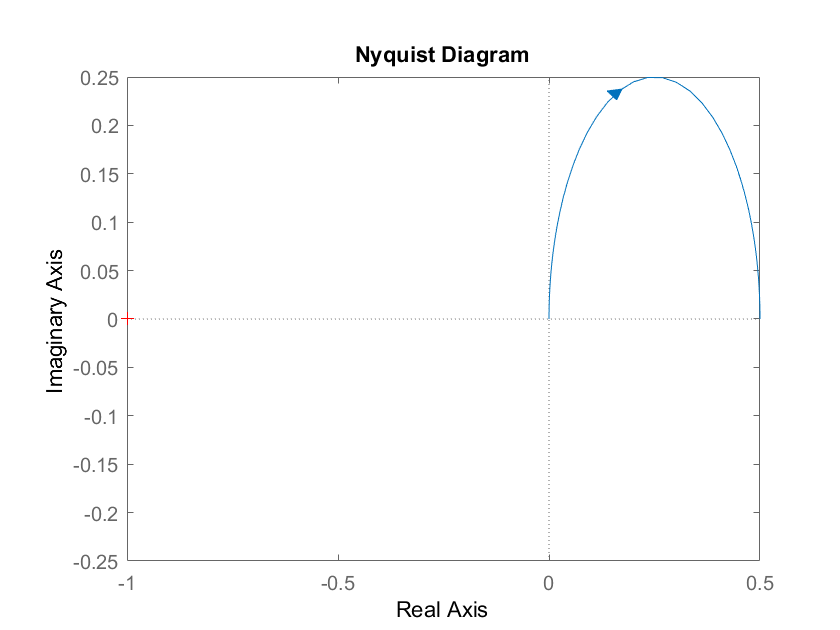

%%
clear all; clc;
R=1; L=0.001;
s=tf('s');
Zp=1/(1/(R)+1/(s*L));
Z=Zp+R;
H=Zp/Z;
ny=nyquistplot(H);
setoptions(ny,'ShowFullContour','off')

## Aufgabe 5

clear all; clc;

fres = 10.10e6; w0 = fres*2*pi;
Rp = 5250;

phi1 = deg2rad(15.5);
w1 = 2*pi*10.08e6;
phi2 = deg2rad(7.9);
w2 = 2*pi*10.09e6;
phi3 = deg2rad(-7.9);
w3 = 2*pi*10.11e6;


v1 = (w1/w0 - w0/w1);
v2 = (w2/w0 - w0/w2);
v3 = (w3/w0 - w0/w3);
Q = tan(phi1)/v1

Q =    -69.9550e+000


Q = tan(phi2)/v2

Q =    -70.0398e+000


Q = tan(phi3)/v3

Q =    -70.1092e+000


Q = 70;
X = Rp/Q

X =     75.0000e+000



L = X/w0

L =      1.1818e-006


C = 1/(X*w0)

C =    210.1055e-012



% Kontrolle
w0 = 1/(sqrt(L*C))

w0 =     63.4602e+006


f0 = w0/(2*pi)

f0 =     10.1000e+006



ppcomp( par(Rp, j*w1*L, 1/(j*w1*C)), 'Z', 'Ohm')

ans = "Z = 5058.8277 Ohm cis( 15.5095° )"